# Regression: Basics

**Suggested Prework**

[MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html) – a free two-hour introductory tutorial to learn the essentials of MATLAB.

## What is Regression?

Regression refers to a set of statistical techniques for estimating the relationship between a dependent variable (*x*) and one or more independent variables (*y*). In other words, it is a method to model a target (dependent) variable based on other (independent) variables. Regression is widely used for forecasting and making predictions from data.

### Linear Regression

In a simple case, you have one dependent and one independent variable. You can perform a basic linear regression, which models a straight line with the equation $y\;=a_0 +a_1 x$ to define the relationship between these two variables.

load linearData.mat x y

***Task****: Click the ****Run**** button to generate a line with the slope and intercept defined below.*

a1 =-0.3;
a0 =-0.7;
 

plotFit(x,y,[a1 a0]);

  ***Try***

- *Use the sliders to set the slope (*$a_1$*)  and intercept (*$a_0$*) variable values to generate different lines to predict the data.*

- *Set the *`a1`* and *`a0`* values to find the best straight line for the data. Note that there can be multiple combinations of coefficients that work well.*

 **Reflect**

- How easy was it to find the best coefficients?

- How did you determine that the line is a good fit?

- Can you now predict the value of `y` for `x=5`?

imshow("regressSolnIm/linefit.jpg"), title("Solution")

In a subsequent section, you will explore a way to determine the goodness of fit.

### Nonlinear Regression

In a slightly more complex case, you'll want to perform nonlinear regression with a single independent variable, such that $y\;=a_0 +a_1 x+a_2 x^2 +a_3 x^3 +a_4 x^4 +\;\ldotp \ldotp \ldotp$

load nonlinearData.mat x y

***Task****: Use the edit fields to set the coefficient values below (between -3 and 3). *`a4`* and *`a3`* have been prepopulated for convenience. Click the ****Run**** button to generate the plot.*

a4 = 0.2;
a3 = 0.5;
a2 = 2;
a1 = 1;
a0 = -0.2;
 

plotFit(x,y,[a4 a3 a2 a1 a0]);

 **Reflect**

- How easy/difficult was it to find the best coefficients?

- How did you determine that the line was a good fit?

- Can you now predict the value of `y` when `x=-4`?

disp("Use the dropdown to reveal a likely solution")

### Multivariable Regression

In a more complex case, you have one dependent variable and several independent variables. In this case, you can use a multivariable or multiple linear regression which follows the equation of a simple plane $y=f\left(x_1 ,x_2 \right)=a*x_1 +b*x_2 +c$

load multivariateData.mat x1 x2 y

***Task****: Click the ****Run**** button to generate a plane with coefficients defined below.*

a =-0.7;
b =-0.3;
c =0.4;
 

plotMultiFit(x1,x2,y,[a b c]);

  ***Try***

- *Use the sliders to set the* $a_2$, $a_1$, and $a_0$ *variable values to generate different planes to model the relationship between *`x1,x2`* and *`y`*.*

- *Set the * $a_2$, $a_1$, and $a_0$ *coefficients to find the best plane to describe the data. Note that this can be very challenging. To aid the process, use the plot tools such as ****Rotate ****and**** Pan**** that appear in the top left of the figure window.*

 **Reflect**

- How easy/difficult was it to find the best coefficients to describe the data?

- How did you determine that the coefficients you chose made a good fit?

disp("Use the dropdown to reveal a likely solution")

## Cost Function

In the example above, you fitted curves and (probably) judged by eye how well the curves estimate the relationship. A more accurate way to evaluate the goodness of the fit is to calculate a cost function. This describes the errors between the predicted value (from a fitted regression model) and the actual values (ground truth). A simple example of a cost function is the Mean Square Error (MSE) function which follows the equation:

 
$$f=\frac{1}{n}\sum_{i=1}^n {\left(Y_i -{\hat{Y} }_i \right)}^2$$


Here, $Y$ denotes the actual observed values of the dependent variable. Predictions are made for a sample of $n$ data points of each independent variable. $\hat{Y}$denotes the prediction made by your model (such as a linear regression model). 

Simply put, MSE is an average of squared prediction errors for a given number of sample data points. Such a measure of goodness can be treated like a ***cost*** to be minimized to estimate the relationship between variables.

load linearData2.mat x y

***Task:**** Fit a linear regression model to predict *`y`* by setting the coefficients *`a1`* and *`a0`*. **Use the MSE value as a guide to improve the selection of coefficients.* 

a1 =-0.5;
a0 =-0.6;
 

yhat = plotFit(x,y,[a1 a0]);
MSE = mean((y-yhat).^2);

text(-2,1,"MSE = " + MSE,"FontSize",14)

The MATLAB variables `y` and `yhat` are numeric vectors containing `n` data points each, corresponding to $Y$ and $\hat{Y}$ in the equation above.

 **Reflect**

- What other cost functions can you use to determine how well your model performs?

## Gradient Descent

To get the most accurate fit, you want to minimize *error*, that is, the difference between the predicted value (from a fitted model) and the actual values (ground truth). In the example above, you tried to find the best coefficients manually. A systematic way to find the best coefficients and to reduce the cost is to apply gradient descent. This is also an optimization problem.

rng(250)
x = -3:0.05:2;
y = (-2*x+0.5) + 0.5*randn(size(x));

***Task:**** Click the ****Run**** button to visualize how gradient descent works.*

learningRate = 0.07;
epochs = 30;
 

[a1,a0,mse] = gradientDescent(x,y,epochs,learningRate);

Here, we consider a simple case with only two coefficients. Visualize the relationship between the MSE and the model coefficients $a_0$ and $a_1$ in a 3-D plot. This plot resembles a valley with one minimum (red dot). Remember, our goal is to reach that minimum. Starting at a point (let's say at one of the top corners), the gradient descent algorithm calculates the direction to go down the valley. This is done in several steps over many iterations or *epochs*. The step size is described by a [*hyperparameter*](https://www.mathworks.com/support/search.html/videos/applied-machine-learning-part-3-hyperparameter-optimization-1547849445386.html?fq=asset_type_name:video%20category:stats/regression-and-anova&page=1) called the *learning rate*.

  ***Try ***

- *Use the sliders to try different learning rates and number of iterations *`epochs`*. Then click the ****Run**** button to observe gradient descent in action.*

- *Set the *`learningRate`* to 0.01.*

- *To combat the low learning rate, increase *`epochs`* to 80.*

- *Set the *`learningRate`* to 0.25 and *`epochs`* to 30.*

- *Increase the *`learningRate`* to 0.35*`.`

 **Reflect**

- What happens when you choose a low learning rate?

- What happens when you choose a high learning rate?

- How does the number of epochs affect the outcome?

As the name implies, this technique requires you to compute the cost function gradients. These are the partial derivatives with respect to each coefficient. The co-efficient is updated by subtracting the respective gradient from its current value in each epoch. For MSE cost function, these are the gradient equations:


$$\frac{d\left(f\right)}{da_1 }=\frac{2\alpha }{n}\sum_{i=1}^n X_i \left({\hat{Y} }_i -Y_i \right)$$
                     
$$\frac{d\left(f\right)}{da_0 }=\frac{2\alpha }{n}\sum_{i=1}^n \left({\hat{Y} }_i -Y_i \right)$$


$\alpha$ is the learning rate.

## Practice Problem

#### Load forecasting

The amount of electricity required to support an electric grid also referred to as the ***load*** on the grid, varies significantly over a day. An example of the load on the grid in downtown New York City is shown below. 

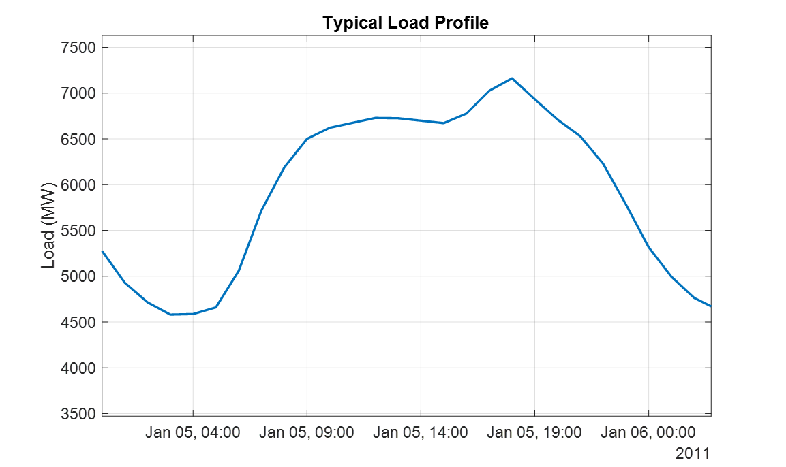

Having a forecast of the electrical load is vital to several entities. It helps utility companies plan how much electricity their power plants will need to produce. It also supports energy traders to gain insight into upcoming market dynamics.

**Can we predict future electrical load requirements?**

**NOTE: **This example requires you to download external data from [New York ISO](http://mis.nyiso.com/public/) and will take approximately 1-5 minutes (depending on your internet connection). A script has been provided to automate the download. 

**  Proceed to the next section only after following these instructions to download the external data.** 

- *Run this section.*

- *When prompted, select a folder to save the data to. Be sure to explicitly select a folder so that it appears in the edit box, before proceeding to click on the ****Select Folder**** button.*

- *The script does ****not*** *download if the data already exists in the selected location.You can change this behavior by opening the script and modifying the relevant dropdown.*

electricityLoadData

As a first step, you will use simple linear regression to predict future electricity load. Therefore, you will use only the electrictiy load as a dependent variable and time as an independent variable.

***Task: ****Select a time granularity for electricity data. Click the ****Run**** button to perform linear regression with time as the independent variable.*

load nyiso_cleaned.mat nyiso

tt = retime(nyiso,"daily","mean")       % Select granularity of data
 

The function [fitlm](https://www.mathworks.com/help/stats/fitlm.html) is used to fit a linear regression model. Convert the `datetime` variable to a numeric values to apply regression.

mdl = fitlm(datenum(tt.Date),tt.HUDVL);
coeffs = mdl.Coefficients
MSE = mdl.MSE

You can [plot](https://www.mathworks.com/help/releases/R2020b/stats/linearmodel.plot.html#responsive_offcanvas) the fitted model to visualize a scatter plot of the data.

plot(mdl)
xticklabels(datestr(xticks))
xtickangle(30)

   ***Try***

- *Use the dropdown menu to choose the granularity of the load data.*

- *Observe the error calculated after clicking ****Run****.*

   **Reflect**

- When does the highest error occur?

- When does the lowest error occur?

- What granularity is the linear regression better for? What does that indicate?

Once the model is available, you can use the [predict](https://www.mathworks.com/help/stats/linearmodel.predict.html) function to compute the dependent variable's value for any given independent variable values.

predDay = 21
predMonth = 8
predYear =2021
 

predDate = datetime(predYear,predMonth,predDay);
predLoad = predict(mdl,datenum(predDate));

disp("Your model predicts a load of "+predLoad+ "MW for "+ datestr(predDate))

In the previous section, although you did not achieve a very accurate forecast for high-granularity data, you still can use the results to predict a general trend.

 ***Quiz: ****Study the results from the task above and select all that apply.*

**A. The electricity load in Hudson Valley is very likely to increase in 2021 compared to 2020.**

increase = false;

**B.** **The electricity load in Hudson Valley is very likely to decrease in 2021 compared to 2020.**

decrease = false;

if increase & ~decrease disp("Correct"); else disp("Try again") ;end

 **Reflect**

- Can you think of any other factors or variables which might influence the electricity load at a given instance?

## 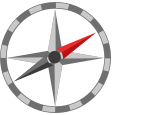Further Exploration

#### Multiple predictors for short-term electricity load forecast

As you may have noticed, with `Date` as the only independent variable, the forecast does not tend to be very accurate at an hourly granularity. 

Independent variables are also referred to as ***explanatory variables*** or ***predictor*** ***variables,*** or simply ***predictors***. A different independent variable or even a combination of variables can improve our ability to fit the data and make predictions. Here, you have been given a function `getMultiPredictors` which generates three different predictors for the hourly electricity load (kWh). 

***Task:**** Run this section to see its results.*

load nyiso_cleaned.mat nyiso
[hourlyLoad,dates,predictors] = getMultiPredictors(nyiso);

disp(predictors)

Fit a multiple linear regression model.

mdl = fitlm(predictors,hourlyLoad);
mdl.Coefficients

"Predict" using the fitted model; that is, apply the model to compare against actual values.

predLoad = predict(mdl,predictors);

Plot the actual and predicted load.

figure
plot(dates,hourlyLoad,"o","MarkerSize",4)
hold on 
plot(dates,predLoad,"r")
hold off
legend("Actual","Predicted")
xlabel("Time")
ylabel("Hourly Load (MW)")
title("Electricity Load: Multiple Linear Regression")

To zoom into a tiny window of time, add the code example below at the end of the section above. 

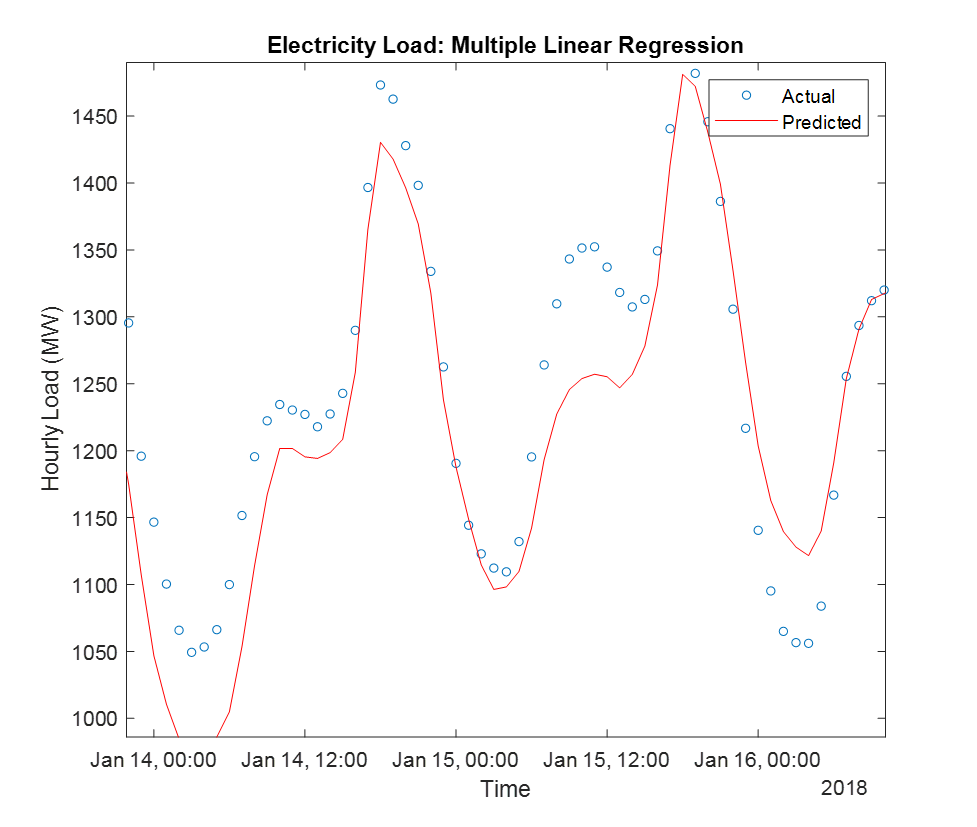

 **Reflect**

Observe the `predictors` variable displayed above. 

- Do you notice a pattern to help identify what physical quantities the three predictors represent? **Hint: **Compare each column with the `hourlyLoad` values.

- What does this tell you about how far into the future our model can forecast? Why?

## Helper functions

Function to plot a single variable regression of any degree.

function yhat = plotFit(x,y,A)
powers = length(A)-1:-1:0;
X = x'.^powers;
yhat = A*X';
 
% Plot
figure("Position",[0 0 600 400],"Color",[0.9 0.9 0.9]);
plot(x,y,"o");
xlim([min(x)-0.5,max(x)+0.5]);
ylim([min(y)-0.5,max(y)+0.5]);
hold on
fplot(@(x)A*(x'.^powers)',"LineWidth",1.5);
hold off
title("y = " + join(A + ["*x^{"+string(powers(1:end-1))+"}",""] ," + "),"Interpreter","tex");
xlabel("x")
ylabel("y or f(x)")

end

Function to plot a plane fit based on coefficients.

function yhat = plotMultiFit(x1,x2,y,coeffs)

[a,b,c] = deal(coeffs(1),coeffs(2),coeffs(3));
yhat = a.*x1 + b.*x2 + c;

% Plot
figure("Position",[0 0 600 400],"Color", [0.9 0.9 0.9]);
scatter3(x1,x2,y);
xlim([min(x1)-0.1,max(x1)+0.1]);
ylim([min(x2)-0.1,max(x2)+0.1]);
zlim([min(y)-0.1,max(y)+0.1]);
[X1,X2] = meshgrid(xlim,ylim);
hold on
surf(X1,X2,a.*X1 + b.*X2 + c,"FaceAlpha", 0.4,"FaceColor",[1 0.5 0.5],"EdgeColor","none");
hold off
title("y = " + a + "x_{1}  +  " + b + "x_{2}  +  " + c);
view([-150 20])
xlabel('x_{1}'), ylabel('x_{2}'), zlabel("y")

end

Function to perform and visualize gradient descent using mean-squared error cost for linear regression.

function [a1,a0,mse] = gradientDescent(x,y,epochs,learningRate)

bgGray = [0.9 0.9 0.9];
figure("Position",[0 0 800 400],"Color",bgGray);

[M,B] = meshgrid(-10:0.1:10,-10:0.1:10);
cost = arrayfun(@(m,b)costFunc(m,b,x,y),M,B);

% Initialize loop   
a1 = 7;                       % initial slope value
a0 = 7;                       % initial intercept value
n = length(x);                % total number of data points      
mse = costFunc(a1,a0,x,y);    % compute initial MSE
r = logspace(-0.5,0,epochs);  % red color intensities for the plots

% Plot three different visualizations
T = tiledlayout(2,2,"TileSpacing","compact","Padding","compact");
    
% Plot 1- surface
nexttile(T,1)
surf(M,B,cost,"EdgeColor","none")
hold on
plot3(a1,a0,mse,"*","Color",[0 0 0]);
hold off
set(gca, "Color",bgGray)
colormap(parula(30))
view([-16 33])
xlabel("a1"), ylabel("a0"), zlabel("Cost (MSE)")

% Plot 2- contour
nexttile(T,2)
contour(M,B,cost,30,"LineWidth",2)
hold on
plot(a1,a0,"*","Color",[0 0 0],"MarkerSize",8)
hold off
set(gca, "Color",bgGray)
xlabel("a1"), ylabel("a0")

% Plot 3- line fit
title(T,"Gradient descent")
nexttile(T,[1,2])
plot(x,y,"o")
set(gca, "Color",bgGray)
hold on
fitLine = plot(xlim,a1.*xlim+a0,"-","LineWidth",1.5,"Color",[0 0 0]);
hold off
ylim([-10,10]), xlabel("x"), ylabel("y")


for step=1:epochs
    
    % Compute gradient descent
    pause(0.02)
    yhat = a1*x + a0;
    diff = yhat - y;
    da1 = learningRate * sum(diff .* x) * 2 / n;
    da0 = learningRate * sum(diff) * 2 / n;
    a1 = a1 - da1;
    a0 = a0 - da0;
    mse = costFunc(a1,a0,x,y);
    
    % Plot new iteration data over the existing plots
    nexttile(T,1)
    hold on
    plot3(a1,a0,mse,"*","Color",[r(step) 0 0]);
    hold off
    
    nexttile(T,2)
    hold on
    plot(a1,a0,"*","Color",[r(step) 0 0],"MarkerSize",8)
    hold off
    
    nexttile(T,3)
    fitLine.YData = a1*xlim+a0;
    fitLine.Color = [r(step) 0 0];
    title("a1 = "+a1 + ", a0 = "+a0, "MSE = "+mse)
  
end
end

Function to compute mean-squared error for a line fit

function mse = costFunc(m,b,x,y)
yhat = m*x+b;
mse = sum((yhat-y).^2)/length(x);
end

Generate multiple predictor variables for hourly load.

function [hourlyLoad,dates,predictors] = getMultiPredictors(nyiso)
tt = retime(nyiso,"hourly","mean");
pred = tt.HUDVL;
N = [7 24 168];
predictors = [[nan(N(1),1); pred(1:end-N(1))],[nan(N(2),1); pred(1:end-N(2))],[nan(N(3),1); pred(1:end-N(3))]];
hourlyLoad = tt.HUDVL;
dates = tt.Date;
end